# Introduction à MATLAB : commande du circuit RC

Dans cet exercice, nous allons étudier le comportement d'un système du premier ordre (circuit RC) en boucle ouverte dans un premier temps. Ensuite nous implémenterons un correcteur proportionnel (P) et étudierons le comportement du système en boucle fermée.

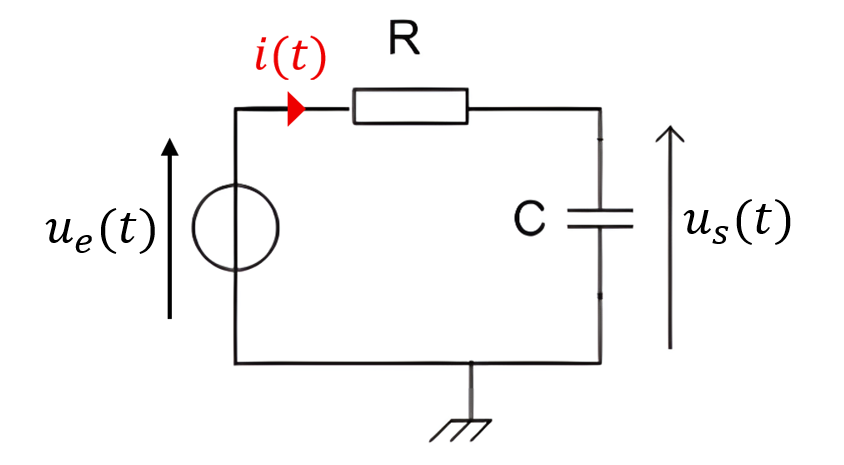

Pour déterminer l'équation différentielle du système, on utilise la loi des mailles : $u_e \left(t\right)=R\ldotp i\left(t\right)+u_s \left(t\right)$.

On rappelle que $i\left(t\right)=C\ldotp \dot{u_s } \left(t\right)$ avec $\dot{u_s } \left(t\right)=\frac{\mathrm{d}}{\mathrm{d}t}u_s \left(t\right)$, donc en remplaçant $i\left(t\right)$ dans la loi des mailles on obtient $e\left(t\right)=R\ldotp C\ldotp \dot{u_s } \left(t\right)+u_s \left(t\right)$.

Pour résoudre cette équation, il existe plusieurs méthodes. Ici, nous allons voir deux méthodes : l'utilisation d'un solveur numérique et l'utilisation de la transformée de Laplace et de la librairie "Control System Toolbox" de Matlab.

On considère que le signal d'entrée est un échelon unitaire : $u_e \left(t\right)=1$, pour tout $t>0$.

## 1 - Etude du système en boucle ouverte

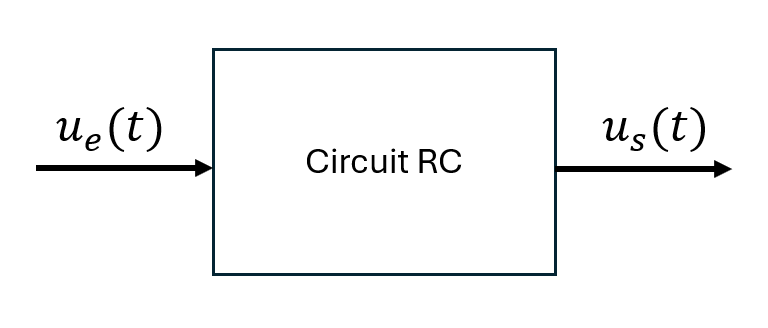

Pour étudier la réponse à un échelon unitaire de ce système en boucle ouverte, nous allons voir deux méthodes :

- Une première méthode qui permet de résoudre l'équation différentielle du système à l'aide d'un solveur numérique.

- Une seconde méthode qui permet de résoudre l'équation différentielle en utilisant la transformée de Laplace comme vu en cours.

### **1.1 - Résolution de l'équation du système dans le domaine temporel à l'aide d'un solveur numérique**

**Question 1 :   **En vous appuyant sur l'exemple ci-dessous, codez la fonction $u_e \left(t\right)=1$ en langage MATLAB.

    Pour déclarer une fonction mathématique avec MATLAB, il faut écrire : "nom_de_la_fonction = @(variables_de_la_fonction) expression_de_la_fonction".

    Exemple de déclaration de la fonction $f\left(t\right)=\sin \left(t\right)+2$ :

    (ici le nom de la fonction est $f$, la variable de la fonction est $t$ et l'expression de cette fonction est $\sin \left(t\right)+2$)

f = @(t) sin(t)+2; % Définition de la fonction f
f(0) % Calcul de la valeur de la fonction pour t=0

ans = 2

    Vous pouvez cliquer sur le bouton RUN pour exécuter le code.

    Déclaration de la fonction $u_e \left(t\right)=1$ :

ue = @(t) 1;

**Question 2 : **Définissez les deux varibles $R=100\;k\Omega$ et $C=5\;\mu F$.

R = 100 * 10^3

R = 100000

C = 5 * 10^-6

C = 5.0000e-06

L'équation différentielle du système peut s'écrire sous la forme $\dot{u_s } \left(t\right)=\frac{1}{\textrm{RC}}\ldotp \left(u_e \left(t\right)-u_s \left(t\right)\right)$. 

Voici comment la coder en MATALB de sorte à ce qu'elle puisse être utilisée dans comme paramètre d'entrée du solveur numérique (ex: fonction ode45) :

s_dot = @(t,us) 1/(R*C) * (ue(t) - us);

**Question 3 : **Utilisez la fonction "ode45" de MATLAB pour résoudre l'équation différentielle exprimée précédement sur l'**intervalle de temps** allant de $t_0 =0$s à $t_f =4$s avec la **condition initiale** $u_s \left(0\right)=0$

    Astuce : Demandez au chat Copilot "Comment utiliser la fonction ode45 ?" pour avoir la documentation et des exemples d'utilisation de cette fonction.

[t, y] = ode45(s_dot, [0 4], 0);

**Question 4 : **En utilisant la fonction plot, tracez la solution de l'équation différentielle trouvée grâce à la fonction ode45.

    Astuce : Demandez au chat Copilot "Comment utiliser la fonction plot ?" pour avoir la documentation et des exemples d'utilisation de cette fonction.

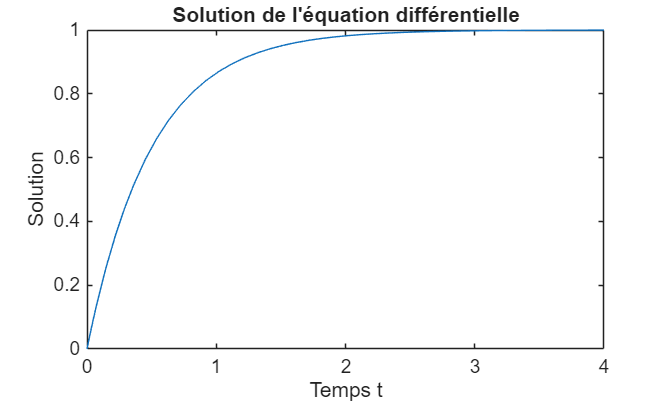

plot(t,y)
title("Solution de l'équation différentielle");
xlabel("Temps t");
ylabel("Solution");

### **1.2 - Résolution de l'équation du système dans le domaine de Laplace**

**Question 5 :** Ecrivez l'équation différentielle du circuit RC $u_e \left(t\right)=R\ldotp C\ldotp \dot{u_s } \left(t\right)+u_s \left(t\right)$ dans le domaine de Laplace.

    
$$U_e \left(p\right)=U_s \left(p\right)\left(1+\mathrm{RC}\ldotp p\right)$$


**Question 6 : **Calculez la fonction de transfert du système $H\left(p\right)=\frac{U_s \left(p\right)}{U_e \left(p\right)}$.

    Fonction de transfert : $H\left(p\right)=\frac{1}{1+\mathrm{RC}\ldotp p}$

**Question 7 : **Complétez le code suivant pour définir la fonction de transfert caclulée dans la question précédente à l'aide de la fonction "tf" :

    Astuce : Demandez au chat Copilot "Comment utiliser la fonction tf ?" pour avoir la documentation et des exemples d'utilisation de cette fonction.

% Définition de la fonction de transfert du circuit RC
num = 1 % A compléter (ex : si le numérateur est "3p + 1" on a "num = [3 1]")

num = 1

den = [R*C 1] % A compléter (ex : si le dénominateur est "5p^2 + 8p + 9" on a "den = [5 8 9]")

den =     0.5000    1.0000


H = tf(num, den)


H =
 
      1
  ---------
  0.5 s + 1
 
Continuous-time transfer function.


    Remarque : lorsque MATLAB affiche la fonction de transfert, il appelle la variable de laplace "s" au lieu de "p" car il utilise la notation américaine.

**Question 8 : **Appliquez un échelon unitaire en entrée su système grâce à la fonction "step".

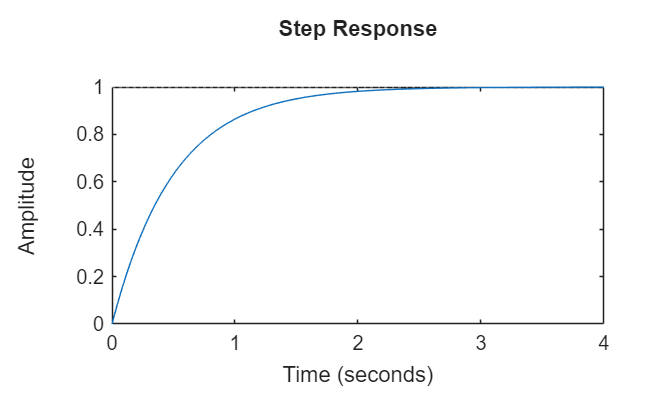

step(H, 4)% A compléter (la fonction step s'utilise comme ceci : step(fonction_de_transfert, temps_final); )

    Vous devriez obtenir la même courbe que celle obtenue à la Question 4.

## 2 - Etude du système en boucle fermée : ajout d'un correcteur proportionnel

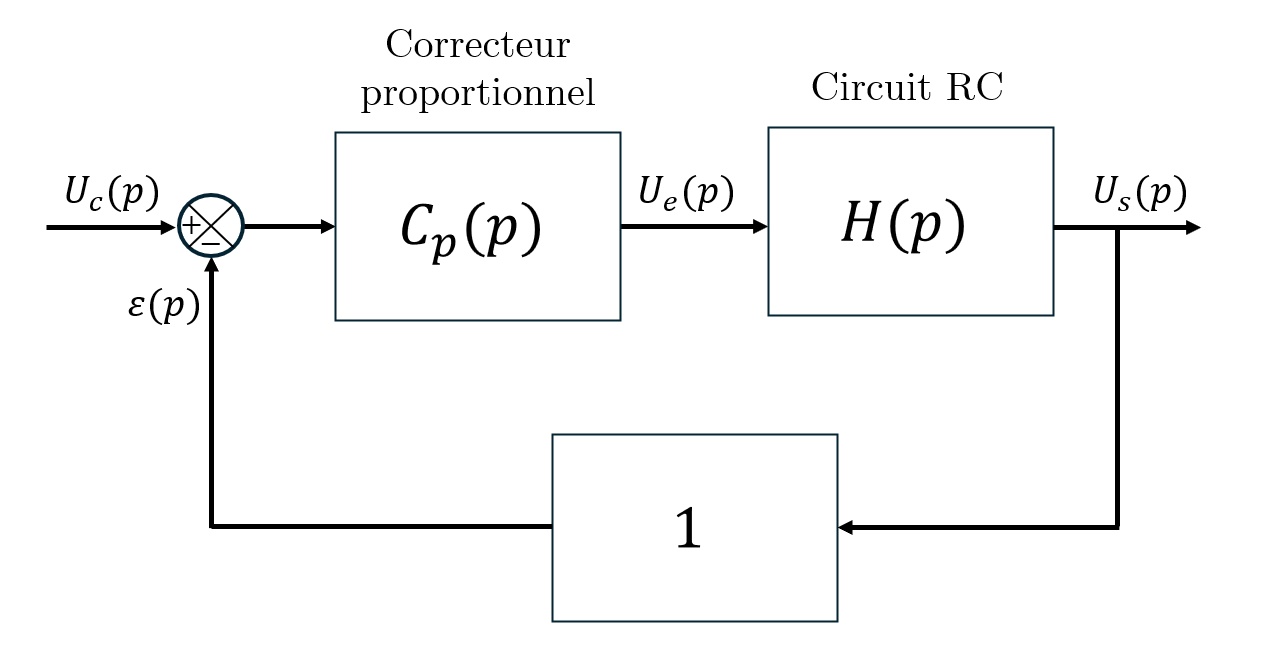

La figure ci-dessus montre le schéma du système en boucle fermée avec $\varepsilon \left(p\right)$ l'erreur entre la tension de sortie $U_s \left(p\right)$ et la tension de consigne $U_c \left(p\right)$.

La fonction de transfert du correcteur proportionnel $C_p \left(p\right)$ est une constante de valeur $K_p$, on donc $C_p \left(p\right)=K_p$. On appelle $K_p$ le gain proportionnel.

Nous allons tester plusieurs valeurs de $K_p$ entre -10 et 100 pour observer l'influence du correcteur sur les performances du système (stabilité, rapidité et précision).

Observons la réponse du système lorsque la valeur de $K_p$ varie à l'aide de l'étude de la fonction de transfert en boucle fermée $\textrm{FTBF}=\frac{\textrm{chaîne}\;\textrm{directe}}{1+\textrm{chaîne}\;\textrm{directe}*\textrm{chaîne}\;\textrm{de}\;\textrm{reotur}}$ en utilisant la fonction "feedback" :

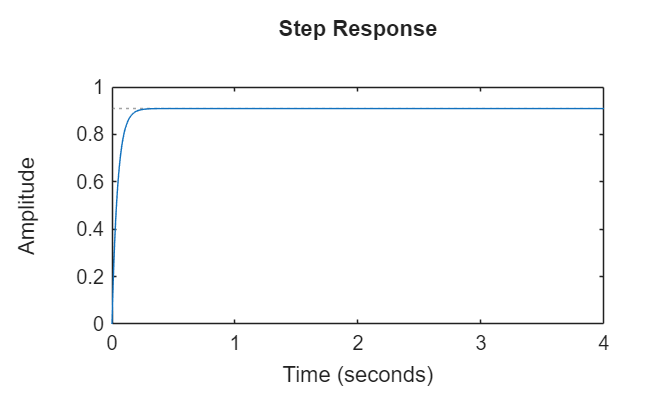

Kp=10; % Faites bouger le curseur pour changer la valeur de K
Cp = tf(Kp); % défintion de la fonction de transfert du correcteur

% Calcul de la fonction de transfert en boucle fermée (FTBO)
FTBF = feedback(Cp * H, 1); % utilisation de la fonction : feedback(chaine_directe,chaine_de_retour)
step(FTBF, 4); % Afficher la réponse en échelon du système en boucle fermée

**Question 9 : **Pour quelle valeur de $K_p$ le système est-il instable ?

    Le système est instable pour $K_p =-10$.

**Question 10 : **Que peut-on dire sur l'influence de $K_p$ sur les performances la précision du système ?

     Plus $K_p$ augmente, plus le système est précis.

**Question 11 : **Que peut-on dire sur l'influence de $K_p$ sur les performances la rapidité du système ?

     Plus $K_p$ augmente, plus le système est rapide.